## Задание 1. Свободное движение 

Параметры для запуска симуляции

simTimeStart = 0;
simTimeEnd = 20;
step = 0.02;
data.time=(simTimeStart:0.02:simTimeEnd)';
input= 0 * ones(1, length(data.time))';
data.signals(1).values=input;
data.signals(1).dimensions=1;

modelName = 'task1'; 

Эксперимент 1-й

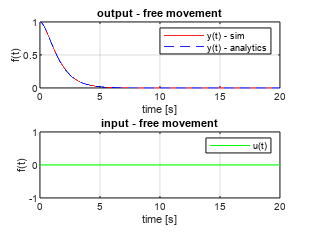

% объявление переменных - характерические корни и начальные условия
lambda1 = -1; lambda2 = -1.5; c1 = 3; c2 = -2;
a0 = lambda1*lambda2; a1 = -(lambda1 + lambda2);
y0 = 1; y1 = 0;

load_system(modelName);
out = sim(modelName, 'StopTime', num2str(simTimeEnd), 'FixedStep',num2str(step));

time = out.simout.Time;                
y_out = out.simout.Data; 
y_analytics = c1*exp(-time) + c2*exp(-1.5*time);

figure;
subplot(2,1,1);
plot(time, y_out, 'r');
hold on;
plot(time, y_analytics, 'b--');
title('output - free movement');   
xlabel('time [s]');                  
ylabel('f(t)');                      
grid on;
legend('y(t) - sim', 'y(t) - analytics');

subplot(2,1,2);
plot(time, input, 'g'); 
title('input - free movement');   
xlabel('time [s]');                  
ylabel('f(t)');                      
grid on;
legend('u(t)');
save_file('output_task1_exp1')

Эксперимент 2-й

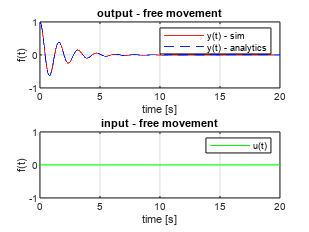

lambda1 = -0.6 + 4j; lambda2 = -0.6 - 4j; c1 = 3/20; c2 = 1;
a0 = lambda1*lambda2; a1 = -(lambda1 + lambda2);
y0 = 1; y1 = 0;

load_system(modelName);
out = sim(modelName, 'StopTime', num2str(simTimeEnd), 'FixedStep',num2str(step));

time = out.simout.Time;                
y_out = out.simout.Data; 
y_analytics = c1*exp(-0.6*time).*sin(4*time) + c2*exp(-0.6*time).*cos(4*time);

figure;
subplot(2,1,1);
plot(time, y_out, 'r');
hold on;
plot(time, y_analytics, 'b--');
title('output - free movement');   
xlabel('time [s]');                  
ylabel('f(t)');                      
grid on;
legend('y(t) - sim', 'y(t) - analytics');

subplot(2,1,2);
plot(time, input, 'g'); 
title('input - free movement');   
xlabel('time [s]');                  
ylabel('f(t)');                      
grid on;
legend('u(t)');
save_file('output_task1_exp2')

Эксперимент 3-й

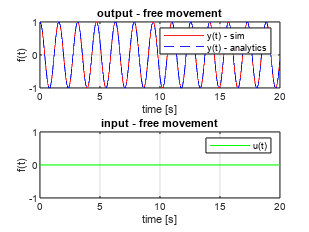

lambda1 = 4j; lambda2 = -4j; c1 = 0; c2 = 1;
a0 = lambda1*lambda2; a1 = -(lambda1 + lambda2);
y0 = 1; y1 = 0;

load_system(modelName);
out = sim(modelName, 'StopTime', num2str(simTimeEnd), 'FixedStep',num2str(step));

time = out.simout.Time;                
y_out = out.simout.Data; 
y_analytics = c1*sin(4*time) + c2*cos(4*time);

figure;
subplot(2,1,1);
plot(time, y_out, 'r');
hold on;
plot(time, y_analytics, 'b--');
title('output - free movement');   
xlabel('time [s]');                  
ylabel('f(t)');                      
grid on;
legend('y(t) - sim', 'y(t) - analytics');

subplot(2,1,2);
plot(time, input, 'g'); 
title('input - free movement');   
xlabel('time [s]');                  
ylabel('f(t)');                      
grid on;
legend('u(t)');
save_file('output_task1_exp3')

Эксперимент 4-й

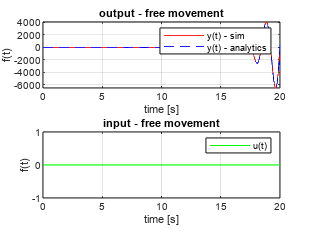

lambda1 = 0.6 + 4j; lambda2 = 0.6 - 4j; c1 = -3/400; c2 = 0.05;
a0 = lambda1*lambda2; a1 = -(lambda1 + lambda2);
y0 = 0.05; y1 = 0;

load_system(modelName);
out = sim(modelName, 'StopTime', num2str(simTimeEnd), 'FixedStep',num2str(step));

time = out.simout.Time;                
y_out = out.simout.Data; 
y_analytics = exp(0.6*time).*(c1*sin(4*time) + c2*cos(4*time));

figure;
subplot(2,1,1);
plot(time, y_out, 'r');
hold on;
plot(time, y_analytics, 'b--');
title('output - free movement');   
xlabel('time [s]');                  
ylabel('f(t)');                      
grid on;
legend('y(t) - sim', 'y(t) - analytics');

subplot(2,1,2);
plot(time, input, 'g'); 
title('input - free movement');   
xlabel('time [s]');                  
ylabel('f(t)');                      
grid on;
legend('u(t)');
save_file('output_task1_exp4')

Эксперимент 5-й

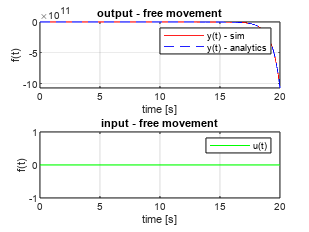

lambda1 = 1; lambda2 = 1.5; c1 = 3/20; c2 = -1/10;
a0 = lambda1*lambda2; a1 = -(lambda1 + lambda2);
y0 = 0.05; y1 = 0;

load_system(modelName);
out = sim(modelName, 'StopTime', num2str(simTimeEnd), 'FixedStep',num2str(step));

time = out.simout.Time;                
y_out = out.simout.Data; 
y_analytics = c1*exp(time) + c2*exp(1.5*time);

figure;
subplot(2,1,1);
plot(time, y_out, 'r');
hold on;
plot(time, y_analytics, 'b--');
title('output - free movement');   
xlabel('time [s]');                  
ylabel('f(t)');                      
grid on;
legend('y(t) - sim', 'y(t) - analytics');

subplot(2,1,2);
plot(time, input, 'g'); 
title('input - free movement');   
xlabel('time [s]');                  
ylabel('f(t)');                      
grid on;
legend('u(t)');
save_file('output_task1_exp5')

Эксперимент 6-й

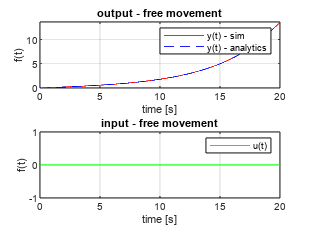

lambda1 = -0.2; lambda2 = 0.2; c2 = 1/4; c1 = -1/4;
a0 = lambda1*lambda2; a1 = -(lambda1 + lambda2);
y0 = 0; y1 = 0.1;

load_system(modelName);
out = sim(modelName, 'StopTime', num2str(simTimeEnd), 'FixedStep',num2str(step));

time = out.simout.Time;                
y_out = out.simout.Data; 
y_analytics = c1*exp(-0.2*time) + c2*exp(0.2*time);

figure;
subplot(2,1,1);
plot(time, y_out, 'r');
hold on;
plot(time, y_analytics, 'b--');
title('output - free movement');   
xlabel('time [s]');                  
ylabel('f(t)');                      
grid on;
legend('y(t) - sim', 'y(t) - analytics');

subplot(2,1,2);
plot(time, input, 'g'); 
title('input - free movement');   
xlabel('time [s]');                  
ylabel('f(t)');                      
grid on;
legend('u(t)');
save_file('output_task1_exp6')

**Функция, чтобы сохранить файл в папку**

function save_file(name)
    path = 'D:\Math\LinearSystemsOfAutoControl\linear_systems_labs\lab2\latex2\images';
    fullpath = fullfile(path, name);
    saveas(gcf, fullpath, 'png');

end